clc
clear

ObservationInfo = rlNumericSpec([3 1]);
ObservationInfo.Name = 'Beamforming States';
ObservationInfo.Description = 'beamRowFrac, beamColFrac','targetRangeIndex';

ObservationInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "Beamforming States"
    Description: "beamRowFrac, beamColFrac"
      Dimension: [3 1]
       DataType: "double"



ActionInfo = rlNumericSpec([1 1],'LowerLimit',-2,'UpperLimit',2);
ActionInfo.Name = 'Beamforming Action';
AverageReward = 0

AverageReward = 0

datalog = [AverageReward 0 0 0];
StepHandle = @(Action,LoggedSignals) RadarEnvSame(Action,LoggedSignals,AverageReward,datalog);
ResetHandle = @() myResetFunction();


env = rlFunctionEnv(ObservationInfo,ActionInfo,StepHandle,ResetHandle);

rng(0);
InitialObs = reset(env)

InitialObs =     0.7672
    0.9219
    0.6154


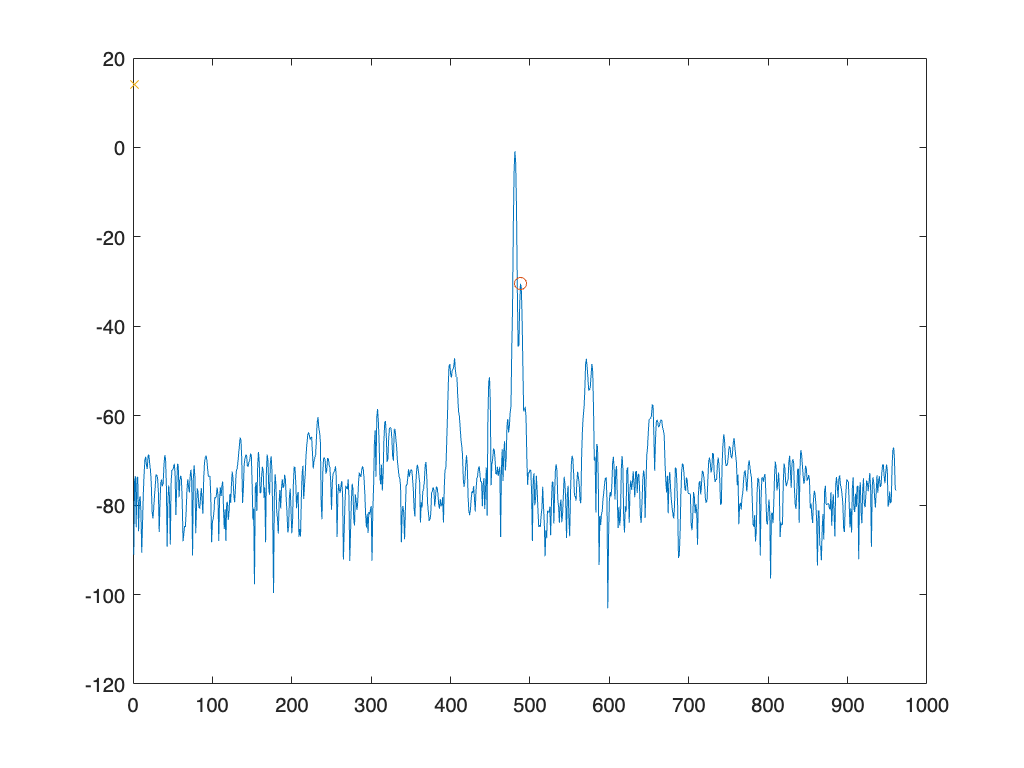

[NextObs,Reward,IsDone,LoggedSignals] = step(env,10);

NextObs

NextObs =     0.7683
    0.9207
    0.6154


numObs = 3

numObs = 3

statePath = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(16,'Name','CriticStateFC1')
    reluLayer('Name', 'CriticRelu1')
    fullyConnectedLayer(8,'Name','CriticStateFC2')];
actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(8,'Name','CriticActionFC1','BiasLearnRateFactor',0)];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph;
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
    
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');
criticNetwork = dlnetwork(criticNetwork);

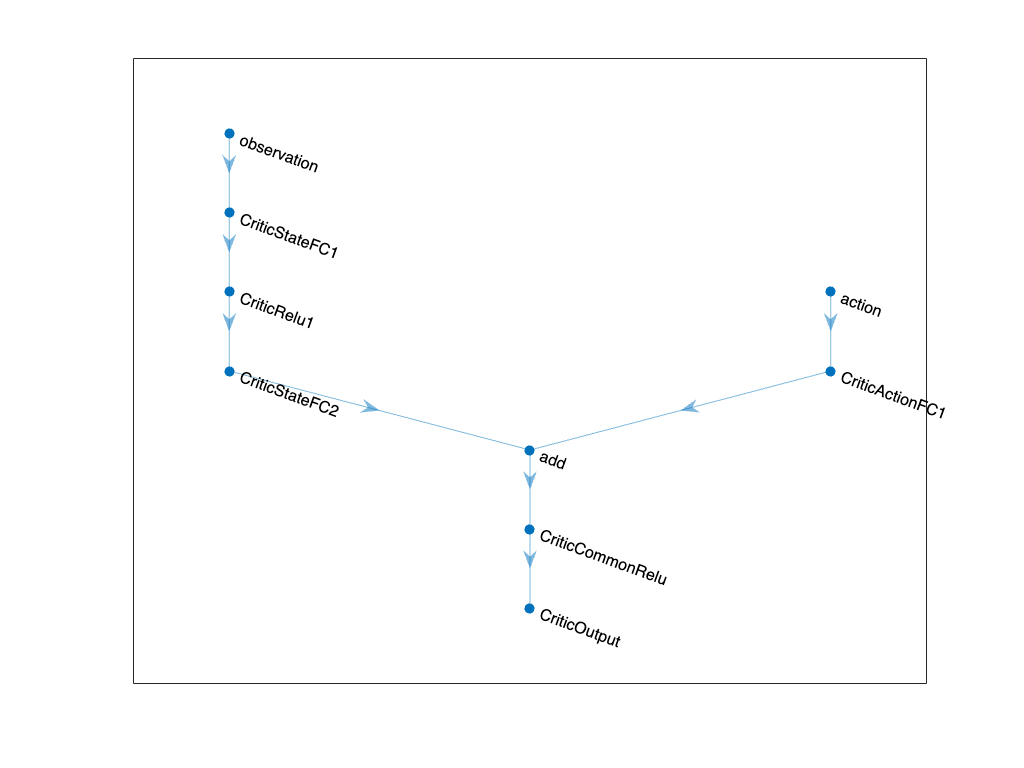

figure
plot(layerGraph(criticNetwork))

criticOpts = rlOptimizerOptions('LearnRate',0.01,'GradientThreshold',1);

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,'ObservationInputNames','observation','ActionInputNames','action');
actInfo

actInfo =   rlNumericSpec with properties:

     LowerLimit: -2
     UpperLimit: 2
           Name: "Beamforming Action"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


actorNetwork = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(16,'Name','ActorFC2')
    reluLayer('Name', 'ActorRelu2')
    fullyConnectedLayer(8,'Name','ActorFC3')
    reluLayer('Name', 'ActorRelu3')
    fullyConnectedLayer(1,'Name','ActorFC4')
    tanhLayer('Name','ActorTanh')
    scalingLayer('Name','ActorScaling','Scale',max(2))];
actorNetwork = dlnetwork(actorNetwork);

actorOpts = rlOptimizerOptions('LearnRate',0.01,'GradientThreshold',1);

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

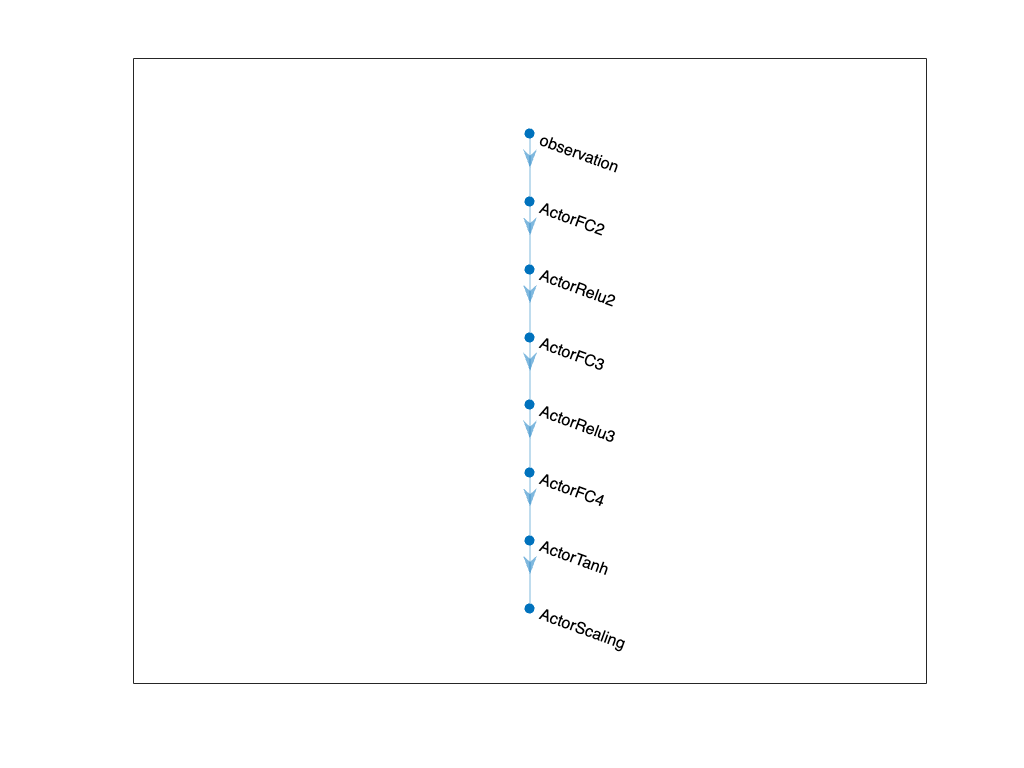

figure
plot(layerGraph(actorNetwork))

Ts = 0.2;
Tf = 10;
agentOpts = rlDDPGAgentOptions(...
    'CriticOptimizerOptions',criticOpts,...
    'ActorOptimizerOptions',actorOpts,...
    'ExperienceBufferLength',1e6,...
    'DiscountFactor',0.95,...
    'MiniBatchSize',8);

agentOpts.NoiseOptions.Variance = 0.6;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-3;

agent = rlDDPGAgent(actor,critic,agentOpts);

maxepisodes = 25;
maxsteps = 20;
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'ScoreAveragingWindowLength',3,...
    'Verbose',true,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',1580,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',1530,...
'SaveAgentDirectory','IRP/ddpge30/d.99');
%trainOpts.UseParallel = true;
%trainOpts.ParallelizationOptions.Mode = "async";
%trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 20;

Episode:   1/ 25 | Episode reward:  1017.72 | Episode steps:   20 | Average reward:  1017.72 | Step Count:   20 | Episode Q0:     2.77


Episode:   2/ 25 | Episode reward:   986.54 | Episode steps:   20 | Average reward:  1002.13 | Step Count:   40 | Episode Q0:    14.57


Episode:   3/ 25 | Episode reward:  1016.85 | Episode steps:   20 | Average reward:  1007.04 | Step Count:   60 | Episode Q0:    41.52


Episode:   4/ 25 | Episode reward:   975.10 | Episode steps:   20 | Average reward:   992.83 | Step Count:   80 | Episode Q0:    58.54


Episode:   5/ 25 | Episode reward:  1034.25 | Episode steps:   20 | Average reward:  1008.73 | Step Count:  100 | Episode Q0:    47.53


Episode:   6/ 25 | Episode reward:   964.03 | Episode steps:   20 | Average reward:   991.13 | Step Count:  120 | Episode Q0:    51.95


Episode:   7/ 25 | Episode reward:   971.53 | Episode steps:   20 | Average reward:   989.94 | Step Count:  140 | Episode Q0:    52.68


Episode:   8/ 25 | Episode reward:   960.10 | Episode steps:   20 | Average reward:   965.22 | Step Count:  160 | Episode Q0:    49.35


Episode:   9/ 25 | Episode reward:   964.46 | Episode steps:   20 | Average reward:   965.36 | Step Count:  180 | Episode Q0:    58.02


Episode:  10/ 25 | Episode reward:   941.76 | Episode steps:   20 | Average reward:   955.44 | Step Count:  200 | Episode Q0:    51.76


Episode:  11/ 25 | Episode reward:   958.88 | Episode steps:   20 | Average reward:   955.03 | Step Count:  220 | Episode Q0:    54.51


Episode:  12/ 25 | Episode reward:   948.50 | Episode steps:   20 | Average reward:   949.71 | Step Count:  240 | Episode Q0:    47.70


Episode:  13/ 25 | Episode reward:   959.04 | Episode steps:   20 | Average reward:   955.47 | Step Count:  260 | Episode Q0:    53.49


Episode:  14/ 25 | Episode reward:   953.25 | Episode steps:   20 | Average reward:   953.60 | Step Count:  280 | Episode Q0:    47.95


Episode:  15/ 25 | Episode reward:   996.70 | Episode steps:   20 | Average reward:   969.66 | Step Count:  300 | Episode Q0:    57.17


Episode:  16/ 25 | Episode reward:   950.12 | Episode steps:   20 | Average reward:   966.69 | Step Count:  320 | Episode Q0:    49.70


Episode:  17/ 25 | Episode reward:   956.25 | Episode steps:   20 | Average reward:   967.69 | Step Count:  340 | Episode Q0:    56.31


Episode:  18/ 25 | Episode reward:   967.17 | Episode steps:   20 | Average reward:   957.85 | Step Count:  360 | Episode Q0:    51.00


Episode:  19/ 25 | Episode reward:   983.03 | Episode steps:   20 | Average reward:   968.82 | Step Count:  380 | Episode Q0:    54.38


Episode:  20/ 25 | Episode reward:   975.37 | Episode steps:   20 | Average reward:   975.19 | Step Count:  400 | Episode Q0:    56.66


Episode:  21/ 25 | Episode reward:   996.30 | Episode steps:   20 | Average reward:   984.90 | Step Count:  420 | Episode Q0:    53.64


Episode:  22/ 25 | Episode reward:   971.80 | Episode steps:   20 | Average reward:   981.16 | Step Count:  440 | Episode Q0:    56.89


Episode:  23/ 25 | Episode reward:   956.31 | Episode steps:   20 | Average reward:   974.80 | Step Count:  460 | Episode Q0:    55.57


Episode:  24/ 25 | Episode reward:   950.78 | Episode steps:   20 | Average reward:   959.63 | Step Count:  480 | Episode Q0:    56.94


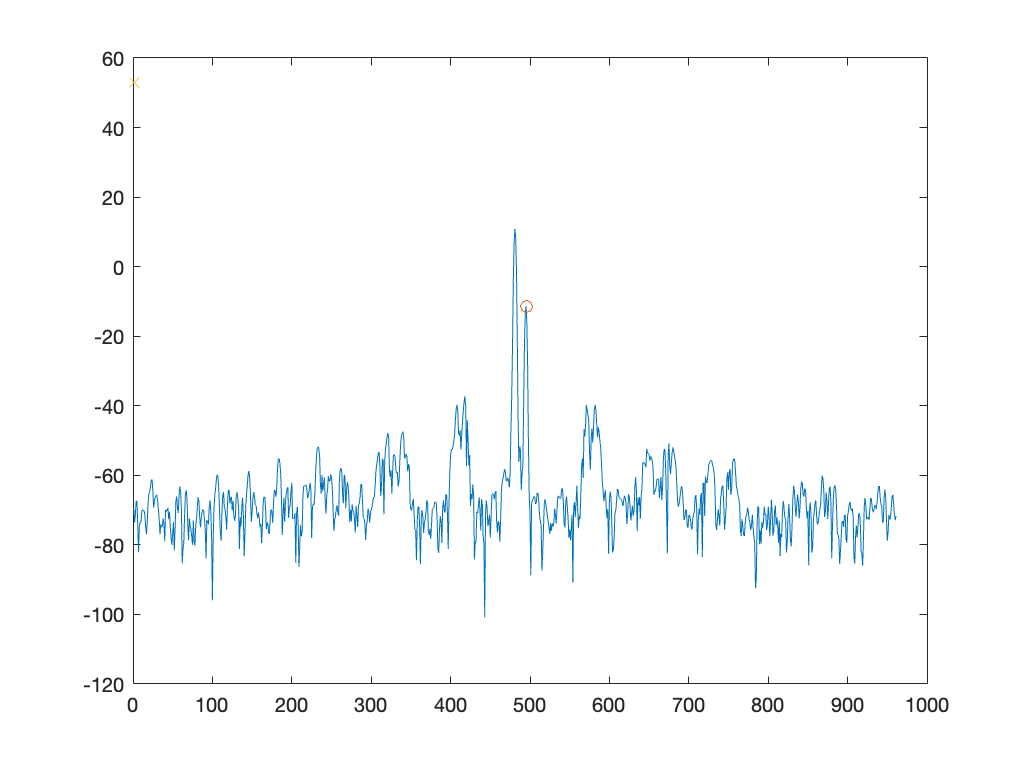

Episode:  25/ 25 | Episode reward:   952.92 | Episode steps:   20 | Average reward:   953.34 | Step Count:  500 | Episode Q0:    54.98



doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('/Users/danukatheja/Downloads/IRP/Cranfield Dropoff Service-pS9cskDSAD72goFo/IRP/Agent24.mat','agent');
end

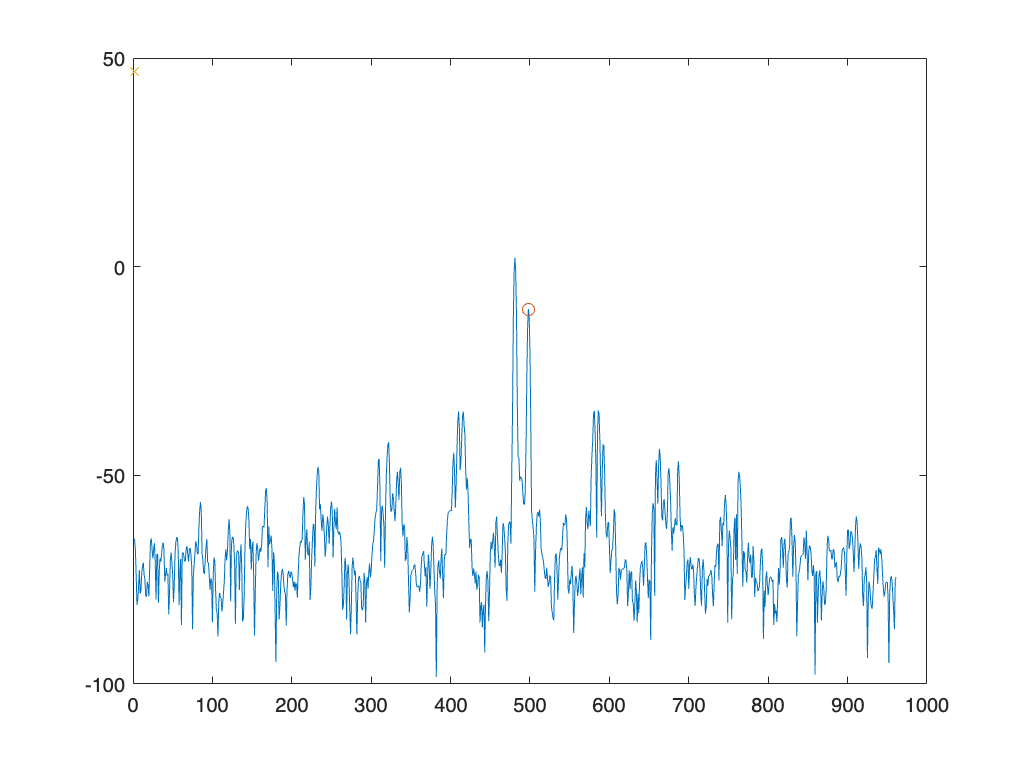


simOptions = rlSimulationOptions('MaxSteps',40);
experience = sim(env,agent,simOptions);

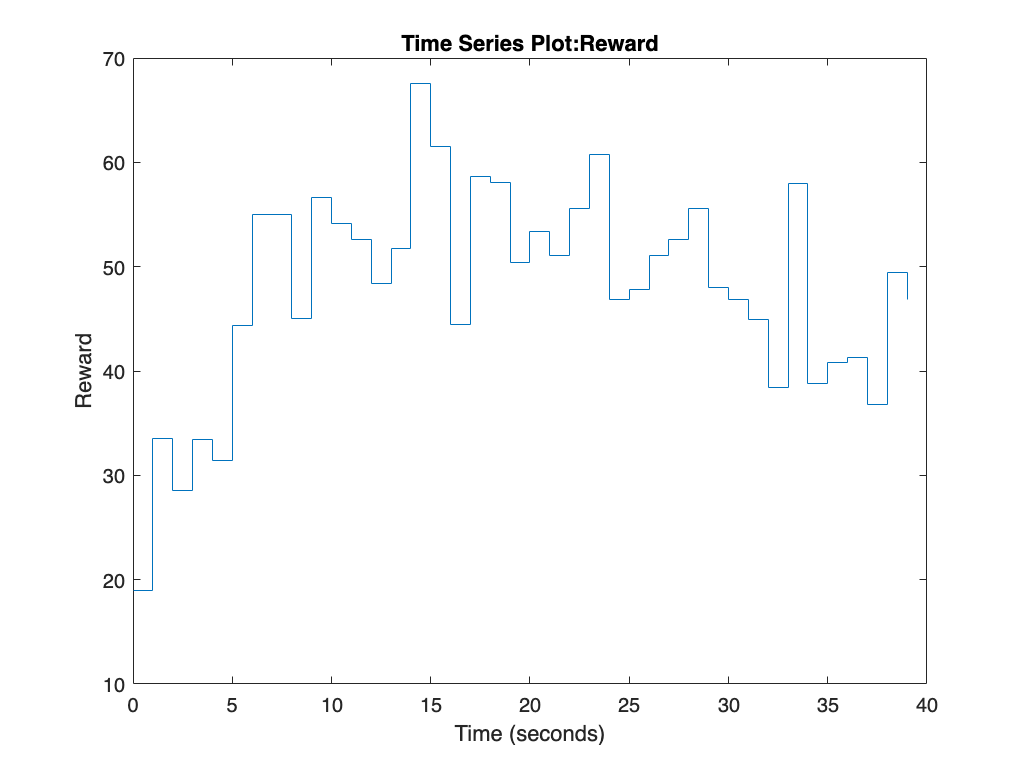

re = experience.Reward;
plot(re)

%sumRe = re.sum

act = experience.Action;
obs = experience.Observation;

act.BeamformingAction

  timeseries

  Common Properties:
            Name: 'Beamforming Action'
            Time: [40x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [1x1x40 double]
        DataInfo: 

obs.BeamformingStates

  timeseries

  Common Properties:
            Name: 'Beamforming States'
            Time: [41x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [3x1x41 double]
        DataInfo: 

plot(act.BeamformingAction)

experience.Reward.sum

ans = 1.9147e+03

Action = act.BeamformingAction.Data(1,1,:)

Action = Action(:,:,1) =

   -1.9999


Action(:,:,2) =

   -1.9999


Action(:,:,3) =

   -1.9999


Action(:,:,4) =

   -1.9999


Action(:,:,5) =

   -1.9999


Action(:,:,6) =

   -1.9999


Action(:,:,7) =

   -1.9999


Action(:,:,8) =

   -1.9999


Action(:,:,9) =

   -1.9999


Action(:,:,10) =

   -1.9999


Action(:,:,11) =

   -1.9999


Action(:,:,12) =

   -1.9999


Action(:,:,13) =

   -1.9999


Action(:,:,14) =

   -1.9999


Action(:,:,15) =

   -1.9999


Action(:,:,16) =

   -1.9999


Action(:,:,17) =

   -1.9999


Action(:,:,18) =

   -1.9999


Action(:,:,19) =

   -1.9999


Action(:,:,20) =

   -1.9999


Action(:,:,21) =

   -1.9999


Action(:,:,22) =

   -1.9999


Action(:,:,23) =

   -1.9999


Action(:,:,24) =

   -1.9999


Action(:,:,25) =

   -1.9999


Action(:,:,26) =

   -1.9999


Action(:,:,27) =

   -1.9999


Action(:,:,28) =

   -1.9999


Action(:,:,29) =

   -1.9999


Action(:,:,30) =

   -1.9999


Action(:,:,31) =

   -1.9999


Action(:,:,32) =

   -1.9999


Action(:

data = [experience.Reward.Data]

data =    19.0086
   33.5269
   28.4995
   33.4678
   31.4643
   44.3871
   54.9854
   55.0382
   45.0572
   56.6687


writematrix(data,'Agent25.CSV');